# Model NR NTN Channel

This example shows how to model two types of New Radio (NR) non-terrestrial network (NTN) channels: a flat fading narrowband channel and a frequency selective fading tapped delay line (TDL) channel. These channels are defined in 3GPP TR 38.811 Section 6.7.1. and Section 6.9.2, respectively [1]. These channels are used to model different NTN deployment scenarios, covering both geo-synchronous orbit (GSO) satellites and non geo-synchronous orbit (NGSO) satellites.

## Introduction

In this example, you generate the path gains of NTN channel model by applying the Doppler shift due to satellite movement for the path gains generated from a base channel model. The base channel model for the NTN flat fading narrowband channel is implemented per ITU-R P.681-11, which defines the propagation data for a land mobile-satellite (LMS) channel [4]. The base channel model for the NTN frequency selective TDL channel is implemented per 3GPP TR 38.901, which defines the terrestrial TDL channel [2].

The Doppler shift due to satellite movement depends on the satellite orbit, elevation angle, and carrier frequency. The Doppler shift due to satellite motion, $f_{d,\textrm{sat}}$, as defined in 3GPP TR 38.811 Section 6.7.1 and Section 6.9.2 [1], is:

 
$$f_{d,\textrm{sat}} =\left(\frac{\nu_{\textrm{sat}} \;}{c}\right)*\left(\frac{R}{R+h}\;\cos \left(\alpha_{\textrm{model}} \right)\right)*f_c$$


- $c$ is the speed of light ($299792458\;\frac{m}{s}$).

- $R$ is the earth radius ($6371000\;m$).

- $h$ is the satellite altitude.

- $\alpha_{\textrm{model}}$ is the satellite elevation angle.

- $f_c$ is the carrier frequency.

- $\nu_{\textrm{sat}}$ is the satellite speed and is given by$\sqrt{\frac{\;\textrm{GM}}{\left(R+h\right)}}$, where G is gravitational constant ($6\ldotp 6743*{10}^{-11} \frac{m^3 }{\textrm{kg}\;s^2 }$) and M is mass of Earth ($5\ldotp 9722*{10}^{24} \;\textrm{kg}$).

This example uses:

- `dopplerShiftCircularOrbit` function to calculate the Doppler shift due to satellite movement.

- `p681LMSChannel` System object™ to model the NTN narrowband channel

- `nrTDLChannel` System object™ to model the NTN TDL channel

## Set NTN Channel Common Parameters

Set the common parameters required to model an NTN narrowband flat fading channel and NTN TDL channel. This example models a low Earth orbit (LEO) satellite moving at an altitude of 600 km and is operating in the S-band. Assume a mobile or UE speed of 3 km/hr. These default parameters are from 3GPP TR 38.821 Table 6.1.2-4 [3].

commonParams = struct;
commonParams.CarrierFrequency = 2e9;              % In Hz
commonParams.ElevationAngle = 50;                 % In degrees
commonParams.SatelliteAltitude = 600000;          % In m
commonParams.MobileAltitude = 0;                  % In m
commonParams.MobileSpeed = 3*1000/3600;           % In m/s
commonParams.SampleRate = 7680000;                % In Hz
% Set the random stream and seed, for reproducibility
commonParams.RandomStream = "mt19937ar with seed";
commonParams.Seed = 73;
% Set the number of sinusoids used in generation of Doppler spread
commonParams.NumSinusoids = 48;
% Calculate the Doppler shift due to satellite movement
satelliteDopplerShift = dopplerShiftCircularOrbit(...
    commonParams.ElevationAngle,commonParams.SatelliteAltitude,...
    commonParams.MobileAltitude,commonParams.CarrierFrequency);
% Calculate the maximum Doppler shift due to mobile movement
c = physconst('lightspeed');
mobileMaxDoppler = commonParams.MobileSpeed*commonParams.CarrierFrequency/c;

## NTN Narrowband Channel

This example supports all the land-mobile satellite (LMS) scenarios available for the NTN flat fading narrowband channel, as defined in 3GPP TR 38.811 Section 6.7.1 [1]. The LMS scenarios defined for S-band are:

- Urban

- Suburban

- RuralWooded

- Residential

The LMS scenarios defined for Ka-band are:

- Suburban

- RuralWooded

Follow these steps to model the NTN flat fading narrowband channel, as specified in 3GPP TR 38.811 Section 6.7.1 [1].

- Set the channel parameters specific to an NTN flat fading narrowband channel.

- Generate the NTN flat fading narrowband channel.

- Visualize the spectrum of the faded or filtered signal.

The NTN flat fading channel is used for narrowband single-input-single-output (SISO) simulations.

### Set NTN Narrowband Channel Parameters

Set the NTN flat fading narrowband channel parameters using the defined common parameters and the parameters specific to NTN narrowband channel. This example configures an urban LMS scenario for the NTN narrowband channel.

% Initialize the NTN flat fading narrowband channel
ntnNarrowbandChan = p681LMSChannel;
ntnNarrowbandChan.SampleRate = commonParams.SampleRate;
ntnNarrowbandChan.CarrierFrequency = commonParams.CarrierFrequency;
ntnNarrowbandChan.ElevationAngle = commonParams.ElevationAngle;
ntnNarrowbandChan.MobileSpeed = commonParams.MobileSpeed;
ntnNarrowbandChan.SatelliteDopplerShift = satelliteDopplerShift;
ntnNarrowbandChan.RandomStream = commonParams.RandomStream;
ntnNarrowbandChan.Seed = commonParams.Seed;
ntnNarrowbandChan.Environment = "Urban";
ntnNarrowbandChan.AzimuthOrientation = 0;
ntnNarrowbandChan.FadingTechnique = "Sum of sinusoids";
ntnNarrowbandChan.NumSinusoids = commonParams.NumSinusoids;

% Set the below properties when Environment is set to Custom
if strcmpi(ntnNarrowbandChan.Environment,'Custom')
    ntnNarrowbandChan.StateDistribution = [3.0639 2.9108; 1.6980 1.2602];
    ntnNarrowbandChan.MinStateDuration = [10 6];
    ntnNarrowbandChan.DirectPathDistribution = [-1.8225 -15.4844; 1.1317 3.3245];
    ntnNarrowbandChan.MultipathPowerCoefficients = [-0.0481 0.9434; -14.7450 -1.7555];
    ntnNarrowbandChan.StandardDeviationCoefficients = [-0.4643 -0.0798; 0.3334 2.8101];
    ntnNarrowbandChan.DirectPathCorrelationDistance = [1.7910 1.7910];
    ntnNarrowbandChan.TransitionLengthCoefficients = [0.0744; 2.1423];
    ntnNarrowbandChan.StateProbabilityRange = [0.05 0.1; 0.95 0.9];
end

Get information about the P.681-11 LMS base channel model and check that the channel filter delay is 0 due to the flat fading nature of the channel.

p681ChannelInfo = info(ntnNarrowbandChan)

p681ChannelInfo = struct with fields:
                   PathDelays: 0
           ChannelFilterDelay: 0
    ChannelFilterCoefficients: 1
          NumSamplesProcessed: 0


### Generate NTN Narrowband Channel

Generate the path gains of NTN flat fading narrowband channel and apply channel filtering to a random input signal using the resultant path gains.

% Generate a random input
rng(commonParams.Seed);
in = randn(commonParams.SampleRate,1,'like',1i);

Generate the faded waveform for the NTN flat fading narrowband channel.

[narrowbandOut,narrowbandPathGains,narrowbandSampleTimes] = ...
    ntnNarrowbandChan(in);

### Visualize NTN Narrowband Channel Received Spectrum

Plot the received spectrum of the faded signal from the NTN flat fading narrowband channel.

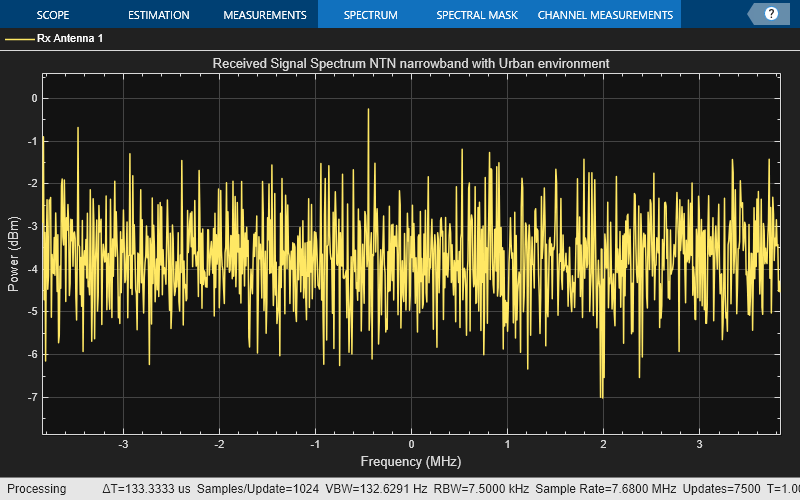

ntnNarrowbandAnalyzer = spectrumAnalyzer( ...
    SampleRate = ntnNarrowbandChan.SampleRate);
ntnNarrowbandAnalyzer.Title = "Received Signal Spectrum " ...
    + "NTN narrowband with " + string(ntnNarrowbandChan.Environment) + " environment";
ntnNarrowbandAnalyzer.ShowLegend = true;
ntnNarrowbandAnalyzer.ChannelNames = "Rx Antenna 1";
ntnNarrowbandAnalyzer(narrowbandOut)

## NTN TDL Channel

This example supports all the four channel profiles of the NTN TDL channel, defined in 3GPP TR 38.811 Section 6.9.2 [1]. These four channel profiles are:

- NTN-TDL-A 

- NTN-TDL-B

- NTN-TDL-C

- NTN-TDL-D 

The channel profiles NTN-TDL-A and NTN-TDL-B are defined for non-line-of-sight (NLOS) conditions. The channel profiles NTN-TDL-C and NTN-TDL-D are defined for line-of-sight (LOS) conditions. All four channel profiles are defined at an elevation angle of 50 degrees. The main differences between the NTN TDL channel [1] and terrestrial TDL channel [2] are:

- NTN TDL channel accounts for Doppler shift due to satellite motion in addition to the Doppler shift due to mobile or user equipment (UE) movement.

- NTN TDL channel delay profiles are different from the terrestrial TDL channel profiles, due to large propagation delays and different scattering environment.

Follow these steps to model the NTN frequency selective fading TDL channel, as specified in 3GPP TR 38.811 Section 6.9.2 [1].

- Set the channel parameters specific to the NTN frequency selective fading TDL channel.

- Generate the NTN frequency selective fading TDL channel.

- Visualize the spectrum of the faded or filtered signal.

### Set NTN TDL Channel Parameters

Set the NTN frequency selective fading TDL channel parameters using the defined common parameters and the parameters specific to NTN TDL channel.

% Initialize the NTN TDL channel
ntnTDLChan = nrTDLChannel;
ntnTDLChan.DelayProfile = "NTN-TDL-A";
ntnTDLChan.DelaySpread = 30e-9;                          % In s
ntnTDLChan.TransmissionDirection = "Downlink";
ntnTDLChan.MIMOCorrelation = "Low";
ntnTDLChan.Polarization = "Co-Polar";
ntnTDLChan.SampleRate = commonParams.SampleRate;
ntnTDLChan.MaximumDopplerShift = mobileMaxDoppler;
ntnTDLChan.SatelliteDopplerShift = satelliteDopplerShift;
ntnTDLChan.RandomStream = commonParams.RandomStream;
ntnTDLChan.Seed = commonParams.Seed;

% Set the antenna configuration
% Modify the below properties, when MIMOCorrelation is set to a value other
% than Custom
if ~strcmpi(ntnTDLChan.MIMOCorrelation,'Custom')
    ntnTDLChan.NumTransmitAntennas = 1;
    ntnTDLChan.NumReceiveAntennas = 2;
else
    % Modify the below properties, when MIMOCorrelation is set to Custom and
    % Polarization is set to Co-Polar or Cross-Polar
    if any(strcmpi(ntnTDLChan.Polarization,{'Co-Polar','Cross-Polar'}))
        ntnTDLChan.TransmitCorrelationMatrix = 1;
        ntnTDLChan.ReceiveCorrelationMatrix = [1 0; 0 1];
    end
    % Modify the below properties, when MIMOCorrelation is set to Custom and
    % Polarization is set to Cross-Polar
    if strcmpi(ntnTDLChan.Polarization,'Cross-Polar')
        ntnTDLChan.TransmitPolarizationAngles = [45 -45];        % In degrees
        ntnTDLChan.ReceivePolarizationAngles = [90 0];           % In degrees
        ntnTDLChan.XPR = 10;                                     % In dB
    end
    % Modify the below property, when both MIMOCorrelation and Polarization
    % are set to Custom
    if strcmpi(ntnTDLChan.Polarization,'Custom')
        ntnTDLChan.SpatialCorrelationMatrix = [1 0; 0 1];
    end
end

Check that the channel is configured for the defined NTN channel delay profile and delay spread by calling the object function `info` to observe the path delays, average path gains, and K factor first tap value.

tdlChanInfo = info(ntnTDLChan)

tdlChanInfo = struct with fields:
          ChannelFilterDelay: 7
         MaximumChannelDelay: 8
                  PathDelays: [0 3.2433e-08 8.5248e-08]
            AveragePathGains: [0 -4.6750 -6.4820]
             KFactorFirstTap: -Inf
         NumTransmitAntennas: 1
          NumReceiveAntennas: 2
    SpatialCorrelationMatrix: [2×2 double]


### Generate NTN TDL Channel

Generate the path gains of the NTN frequency selective fading TDL channel and apply channel filtering to a random input signal using the resultant path gains.

% Generate a random input
rng(commonParams.Seed);
in = randn(commonParams.SampleRate,tdlChanInfo.NumTransmitAntennas,'like',1i);
% Generate the faded waveform for NTN TDL channel
[tdlOut,tdlPathGains,tdlSampleTimes] = ntnTDLChan(in);

### Visualize NTN TDL Channel Received Spectrum

Plot the received spectrum of the faded signal from the NTN frequency selective fading TDL channel.

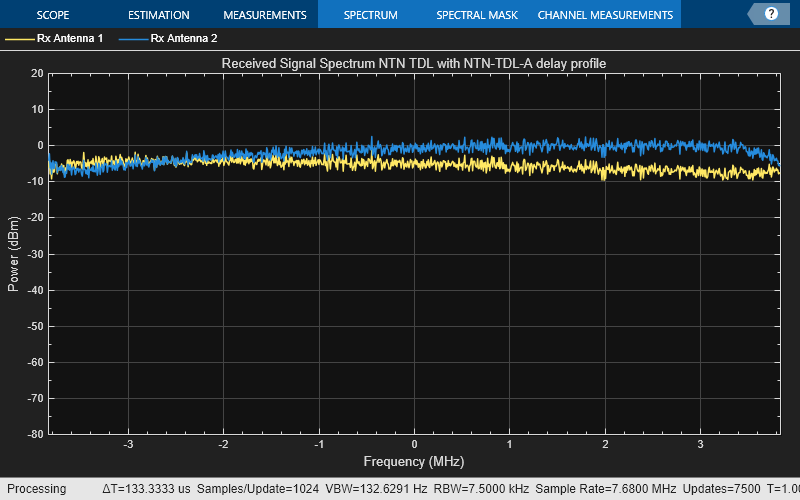

ntnTDLAnalyzer = spectrumAnalyzer(SampleRate = ntnTDLChan.SampleRate);
ntnTDLAnalyzer.Title = "Received Signal Spectrum " ...
    + "NTN TDL with " + string(ntnTDLChan.DelayProfile) + " delay profile";
ntnTDLAnalyzer.ShowLegend = true;
for nRx = 1:size(tdlOut,2)
    ntnTDLAnalyzer.ChannelNames{nRx} = "Rx Antenna " + nRx;
end
ntnTDLAnalyzer(tdlOut)

## Further Exploration

You can use this example to further explore these options:

- To configure and analyze the NTN narrowband or TDL channels for other satellite orbits, change the `SatelliteAltitude` field of the `commonParams` structure.

- To analyze the NTN flat fading narrowband channel for another environment, change the `Environment` property of the `p681LMSChannel`.

- To analyze the NTN TDL channel for LOS delay profiles, change the `DelayProfile` property of the `nrTDLChannel` to NTN-TDL-C or NTN-TDL-D.

- To configure the NTN TDL channel for multiple antennas, change the `MIMOCorrelation` and `Polarization` properties of the `nrTDLChannel`. You might need to set other properties depending on these values.

- Try using the two NTN channel models used in the example in a link simulation and compute the link metric. For more information, see the [NR NTN PDSCH Throughput](docid:satcom_ug#mw_548a2ea2-d6d7-4b55-8842-8af61f373327) example.

## References

[1] 3GPP TR 38.811. "Study on new radio (NR) to support non-terrestrial networks." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

[2] 3GPP TR 38.901. "Study on channel model for frequencies from 0.5 to 100 GHz." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

[3] 3GPP TR 38.821. "Solutions for NR to support non-terrestrial networks (NTN)." 3rd Generation Partnership Project; Technical Specification Group Radio Access Network.

[4] ITU-R Recommendation P.681-11 (08/2019). "Propagation data required for the design systems in the land mobile-satellite service." P Series; Radio wave propagation.

*Copyright 2021-2023 The MathWorks, Inc.*